clear all; close all; clc;
b = [ones(24,1);-5;-10]

b =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1



A = [2*eye(24) 2*eye(24);
    0 0 ones(1,9) zeros(1,37);
    zeros(1,29) ones(1,16) zeros(1,3)]

A =      2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     2     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

## Ax+b=0

x = pinv(A)*(-b);

c1 = x(1:24);
c2 = x(25:48);

c1'*(c1+c2+1)+c2'*(c1+c2+1)

ans = -6.0000

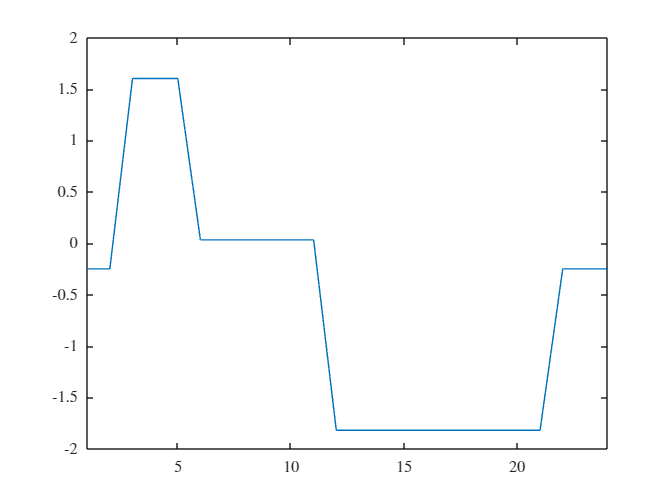


figure()
plot(c1)
xlim([1 24])

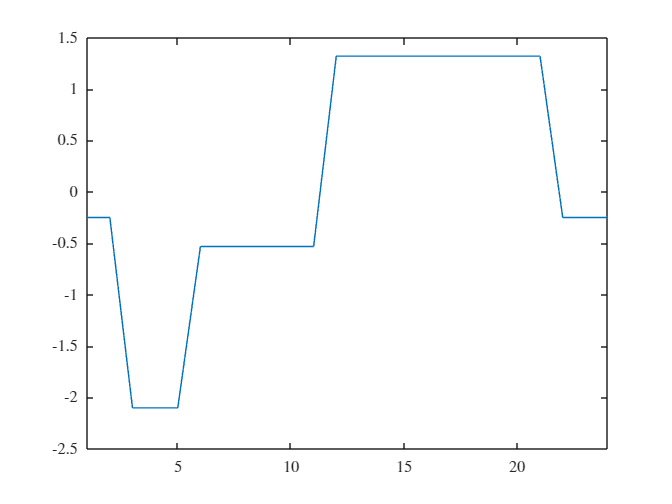


figure()
plot(c2)
xlim([1 24])


sum(c1(3:11))

ans = 5.0000

sum(c2(6:21))

ans = 10.0000

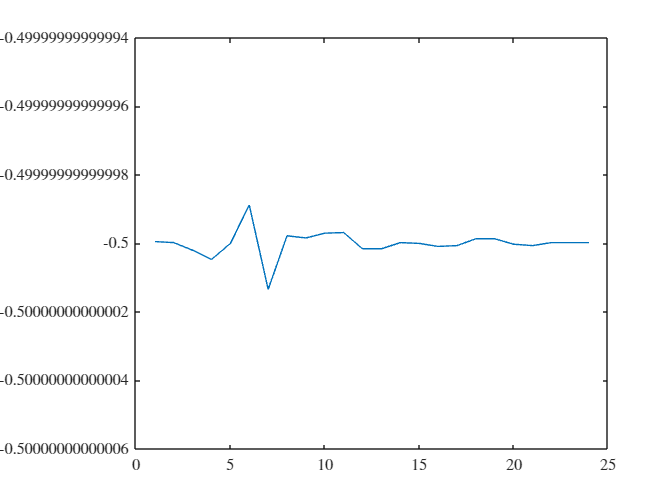


figure()
plot(c1+c2)